# **Projeto 2 - Mecânica dos Sólidos**

format short e

## **Aula 24:** Exercício 1

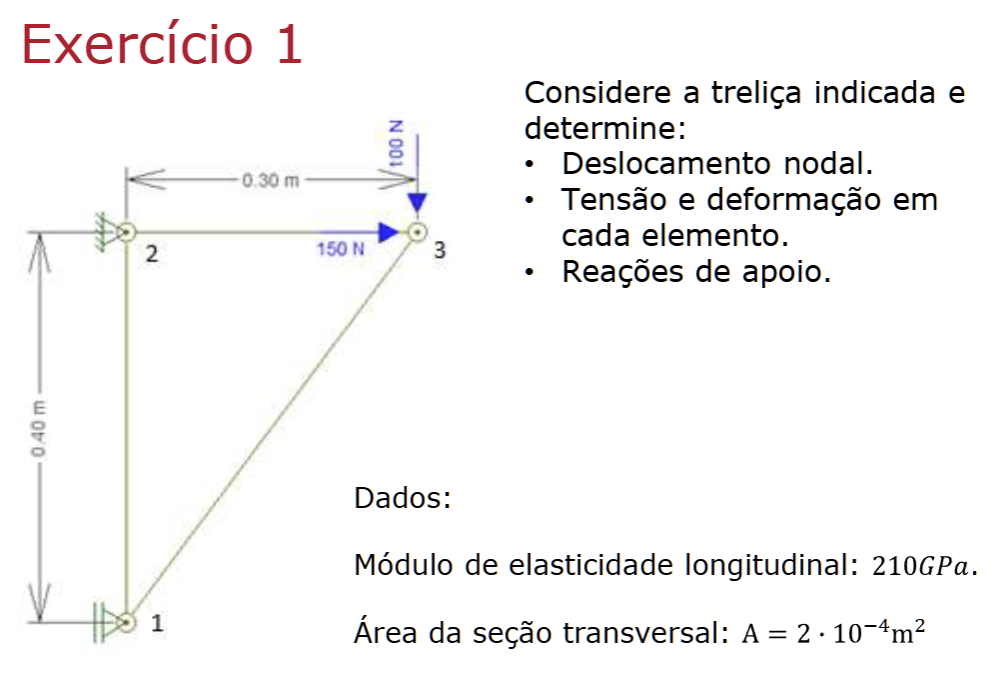

% PASSO 1: Definir a origem do sistema de referência e numerar os nós; elementos; GDL.

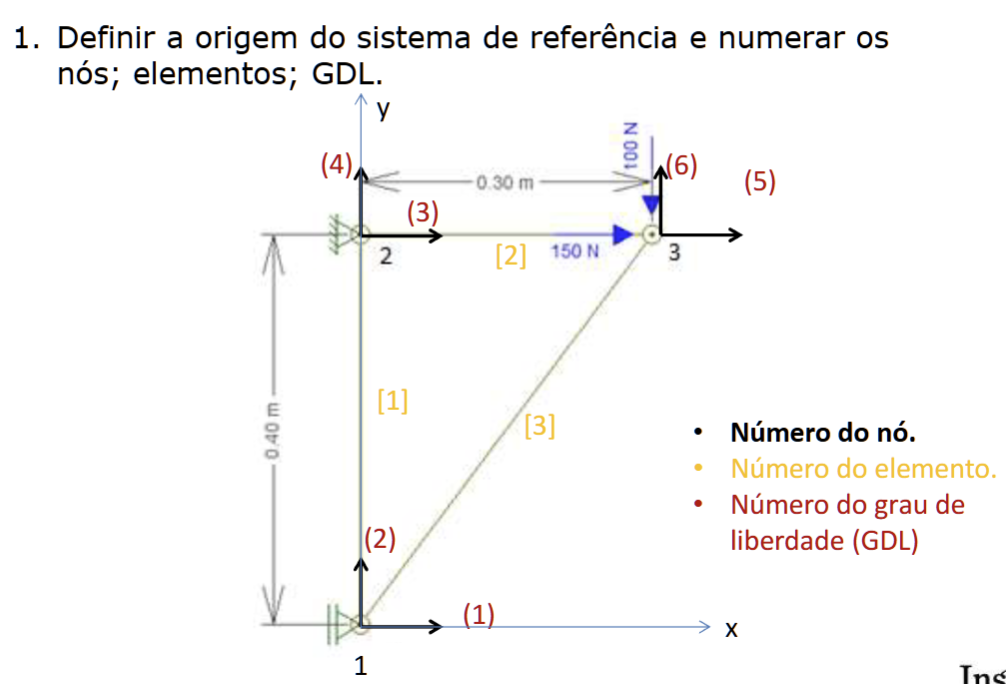

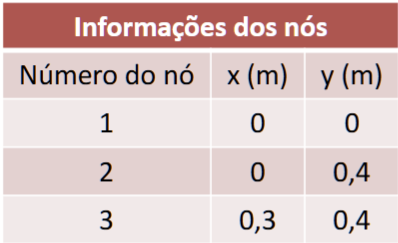

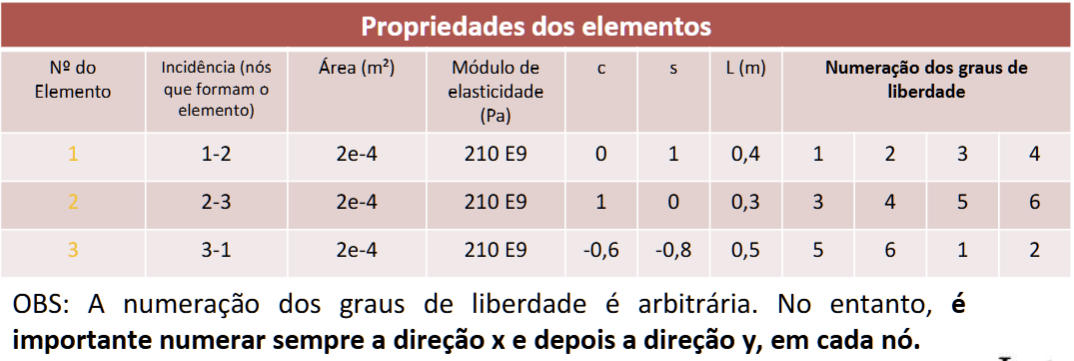

% PASSO 2: Montar a matriz de rigidez de cada elemento
E = 210 * 10^9; % Módulo de elasticidade longitudinal [Pa]
A = 2 * 10^(-4); % Área da seção transversal [m^2]

num_elementos = 3;
num_nos = 3;

% X e Y de cada nó
%       x    y
x_y = [ 0,   0;
        0,   0.4;
        0.3, 0.4];

% ============================================================================

% Comprimento dos elementos (e)
len_elementos = zeros(length(x_y), 1);

% ============================================================================

% Cossenos (c) e senos (s)
%c1 = 0; s1 = 1;
%c2 = 1; s2 = 0;
%c3 = (x1 - x3)/l3; s3 = (y1 - y3)/l3;

cos_sen = zeros(length(x_y), 2);  % cos_sen_el = [ c, s; 
%                                                      ...]

% ============================================================================

% Matrizes de Rigidez de cada elemento (K1, K2, K3, ...)
K = cell(num_elementos, 1);

% ============================================================================

% Calcular os comprimentos (L), os senos (s) e cossenos (c) e Matrizes de
% Rigidez (K)
for i = 1:num_elementos
    if i == num_elementos
        delta_x = x_y(1,1) - x_y(num_elementos,1);
        delta_y = x_y(1,2) - x_y(num_elementos,2);
    else
        delta_x = x_y(i+1,1) - x_y(i,1);
        delta_y = x_y(i+1,2) - x_y(i,2);
    end
    len_elementos(i) = sqrt(delta_x^2 + delta_y^2);   % tamanho elemento

    c = delta_x/len_elementos(i);                     % cosseno
    s = delta_y/len_elementos(i);                     % seno
    cos_sen(i,1) = c;
    cos_sen(i,2) = s;
    
    K{i} = [ c^2,   c*s, -c^2, -c*s;
             c*s,   s^2, -c*s, -s^2;
             -c^2, -c*s,  c^2,  c*s;
             -c*s, -s^2,  c*s,  s^2 ];
    K{i} = E*A/len_elementos(i) * K{i};
end
% VERIFICAR SE OS CALCULOS DE SENO E COSSENO FUNCIONAM PARA TODOS OS
% ELEMENTOS, se tiver mais nos


% PASSO 3: Montar a matriz de rigidez global [Kg] da treliça fazendo asuperposição das matrizes dos elementos.
num_gdl = num_nos*2;
Kg = zeros(num_gdl, num_gdl)

Kg =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



for i = 1:num_elementos
    K_elem = K{i};

    % Monta a matriz de Kg
    if i == num_elementos
        nos = [2*i - 1, 2*i, 1, 2];
        for row = 1:4
            for col = 1:4
                Kg(nos(row), nos(col)) = Kg(nos(row), nos(col)) + K_elem(row, col);
            end
        end
    else 
        for row = 1:4      
            row_kg = (row + 2*(i-1));   % Se i = 1, comeca em 1, se i = 2 comeca em 3, etc ...
            for col = 1:4
                col_kg = (col + 2*(i-1));
                Kg(row_kg, col_kg) = Kg(row_kg, col_kg) + K_elem(row, col);
            end
        end
    end
end
Kg;
% Amo a notação do Matlab, simplesmente uma escadinha de end

% PASSO 4: Montar o vetor global de forças. No grau de liberdade com restrição deve aparecer um esforço de reação.
Pg = zeros(num_elementos*2, 1);

% Vou adicionar manualmente, pq n tem como automatizar isso
Pg(5) = 150;
Pg(6) = -100;

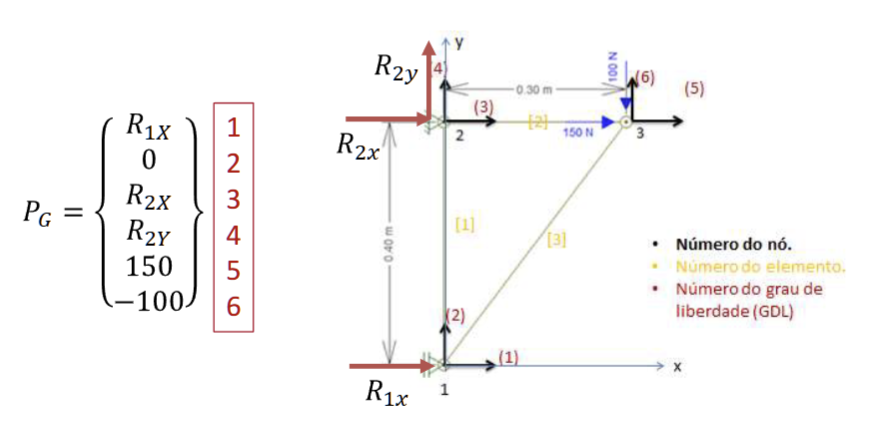

% PASSO 5: Aplicar as condições de contorno (eliminar linha e coluna do grau de liberdade com restrição)

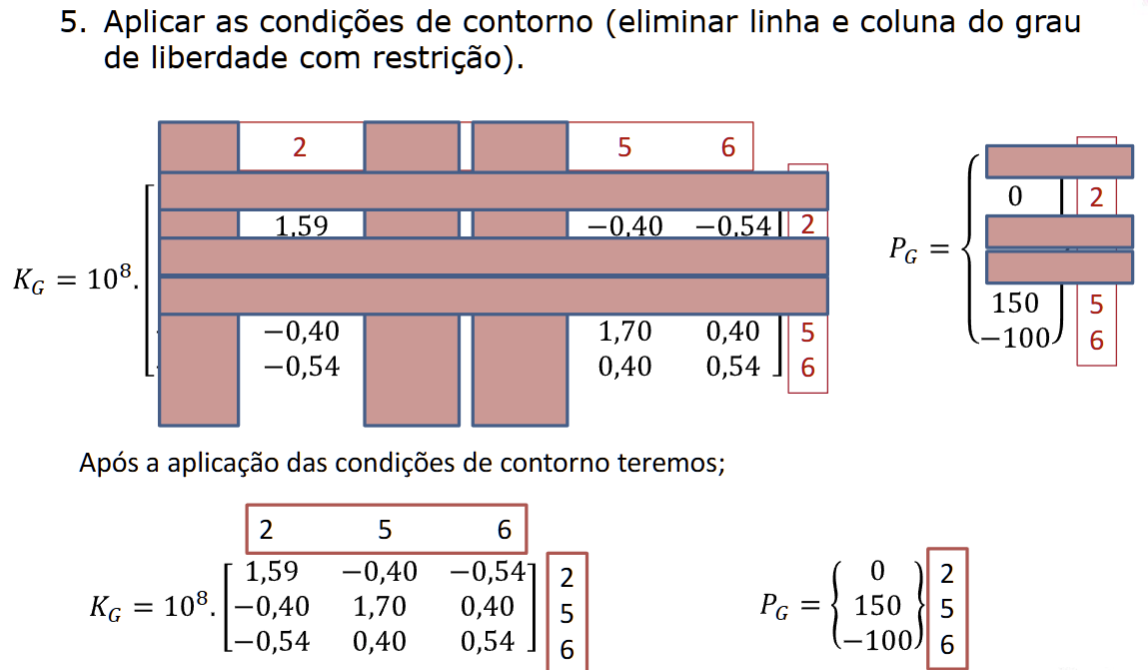

% Aplicando as condições de contorno temos:
Sem_restricao = [2, 5, 6];
num_restri = length(Sem_restricao);

Kg_reduzida = zeros(num_restri, num_restri);
Pg_reduzida = zeros(num_restri, 1);

for i = 1:num_restri
    row = Sem_restricao(i);
    for j = 1:num_restri
        col = Sem_restricao(j);
        Kg_reduzida(i, j) = Kg(row, col);
    end

    Pg_reduzida(i, 1) = Pg(row,1);
end

Kg_reduzida

Kg_reduzida =    1.5876e+08  -4.0320e+07  -5.3760e+07
  -4.0320e+07   1.7024e+08   4.0320e+07
  -5.3760e+07   4.0320e+07   5.3760e+07


Pg_reduzida

Pg_reduzida =      0
   150
  -100


% PASSO 6: Resolver o sistema de equações para a obtenção dos deslocamentos
%                      [Kg_reduzida] {U} = {Pg_reduzida}

U = linsolve(Kg_reduzida, Pg_reduzida);

U_expandida = zeros(num_elementos*2, 1);

for row = 1:num_restri
    i = Sem_restricao(row);
    U_expandida(i) = U(row);
end
U_expandida

U_expandida =             0
  -9.5238e-07
            0
            0
   1.6071e-06
  -4.0179e-06


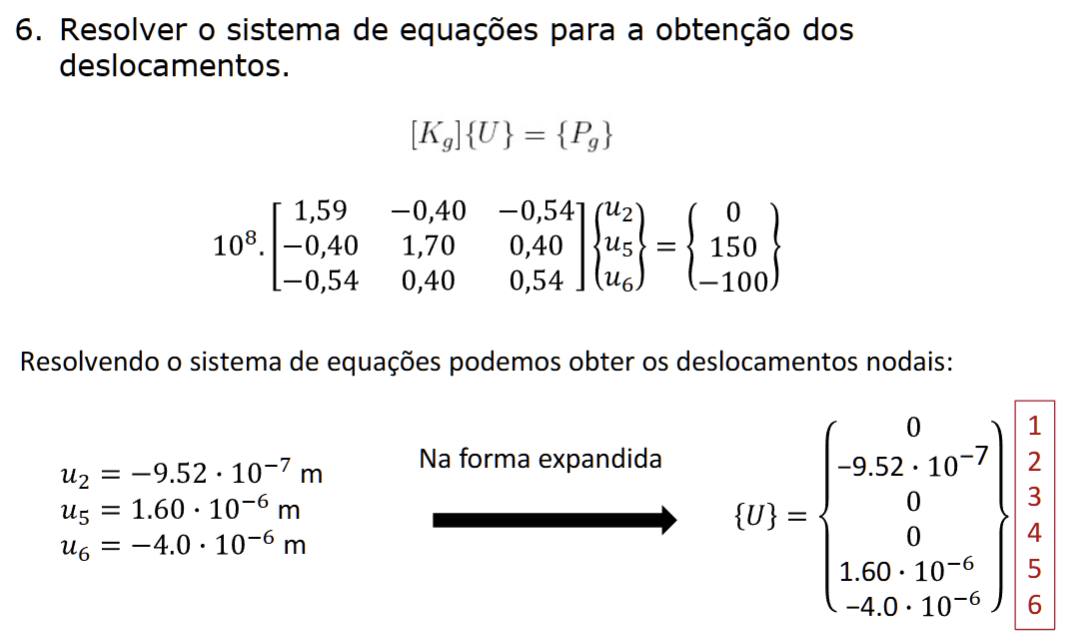

% PASSO 7: Determinar a deformação e a tensão em cada elemento.
deformacao = zeros(num_elementos, 1);  % como cada nó tem 2 u's
tensao = zeros(num_elementos, 1);  % como cada nó tem 2 u's

for i = 1:num_elementos
    c = cos_sen(i,1);
    s = cos_sen(i,2);
    
    if i == num_elementos
        aux = [U_expandida(2*i - 1);  U_expandida(2*i); U_expandida(1); U_expandida(2)];
    else
        index_u = (1 + 2*(i-1));
        aux = [U_expandida(index_u);  U_expandida(index_u+1); U_expandida(index_u+2); U_expandida(index_u+3)];
    end

    deformacao(i, 1) = (1/len_elementos(i,1)) * [-c, -s, c, s] * aux;
end

deformacao

deformacao =    2.3810e-06
   5.3571e-06
  -2.9762e-06


tensoes = E * deformacao

tensoes =    5.0000e+05
   1.1250e+06
  -6.2500e+05


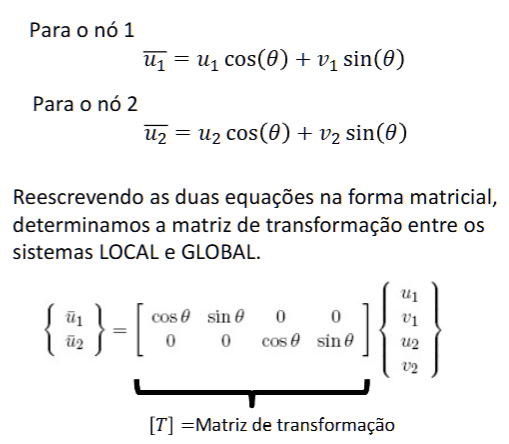

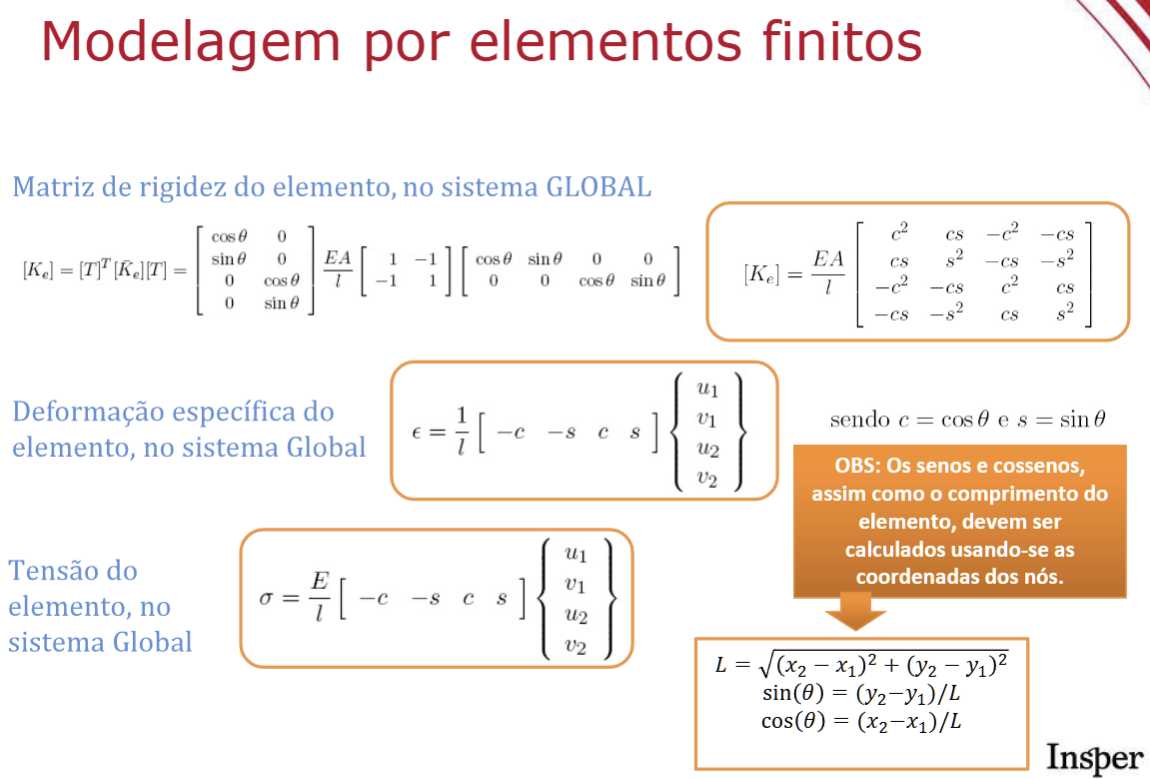

% PASSO 8: Determinar as reações de apoio nos nós com restrição.

Pg_final = Kg * U_expandida

Pg_final =    7.5000e+01
            0
  -2.2500e+02
   1.0000e+02
   1.5000e+02
  -1.0000e+02
